%--------------------------------%
%------------ Import ------------%
%--------------------------------%

format("shortG")

data5C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.27.24.txt").data(:,2);
data5C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.11.09.txt").data(:,2);
data5C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.05.37.txt").data(:,2);

data10C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 12.54.19.txt").data(:,2);
data10C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 16.54.32.txt").data(:,2);
data10C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 20.34.42.txt").data(:,2);

data25C_1_up = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.22.15.txt").data(:,2);
data25C_2_up = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.27.51.txt").data(:,2);
data25C_3_up = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.02.25.txt").data(:,2);

data40C_1 = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 13.52.30.txt").data(:,2);
data40C_2 = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 17.57.29.txt").data(:,2);
data40C_3 = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 21.34.34.txt").data(:,2);

data25C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 14.33.43.txt").data(:,2);
data25C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 18.44.05.txt").data(:,2);
data25C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 17-04-2023 22.33.53.txt").data(:,2);

data10C_1_down = importdata("Christoffer\P3\1.cyklus\Log Data 17-04-2023 15.20.19.txt").data(:,2);
data10C_2_down = importdata("Christoffer\P3\2.cyklus\Log Data 17-04-2023 19.35.12.txt").data(:,2);
data10C_3_down = importdata("Christoffer\P3\3.cyklus\Log Data 18-04-2023 08.48.40.txt").data(:,2);



%--------------------------------%
%-------- Temp Convert ----------%
%--------------------------------%
A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;



eq = @(rs) 1./(A + B*log(rs) + C*log(rs).^(n-1) + D*log(rs).^n) - 273.15;

data5C_1_temp = eq(data5C_1);
data5C_2_temp = eq(data5C_2);
data5C_3_temp = eq(data5C_3);

data10C_1_up_temp = eq(data10C_1_up);
data10C_2_up_temp = eq(data10C_2_up);
data10C_3_up_temp = eq(data10C_3_up);

data25C_1_up_temp = eq(data25C_1_up);
data25C_2_up_temp = eq(data25C_2_up);
data25C_3_up_temp = eq(data25C_3_up);

data40C_1_up_temp = eq(data40C_1);
data40C_2_up_temp = eq(data40C_2);
data40C_3_up_temp = eq(data40C_3);

data25C_1_down_temp = eq(data25C_1_down);
data25C_2_down_temp = eq(data25C_2_down);
data25C_3_down_temp = eq(data25C_3_down);

data10C_1_down_temp = eq(data10C_1_down);
data10C_2_down_temp = eq(data10C_2_down);
data10C_3_down_temp = eq(data10C_3_down);

%--------------------------------%
%------------ Means -------------%
%--------------------------------%


data5C_1_mean = mean(data5C_1_temp);
data5C_2_mean = mean(data5C_2_temp);
data5C_3_mean = mean(data5C_3_temp);
data5C_mean = mean([data5C_1_mean, data5C_2_mean, data5C_3_mean])

data5C_mean =       -3.7643




data10C_1_up_mean = mean(data10C_1_up_temp);
data10C_2_up_mean = mean(data10C_2_up_temp);
data10C_3_up_mean = mean(data10C_3_up_temp);
data10C_mean_up = mean([data10C_1_up_mean, data10C_2_up_mean, data10C_3_up_mean])

data10C_mean_up =        11.038



data25C_1_up_mean = mean(data25C_1_up_temp);
data25C_2_up_mean = mean(data25C_2_up_temp);
data25C_3_up_mean = mean(data25C_3_up_temp);
data25C_mean_up = mean([data25C_1_up_mean, data25C_2_up_mean, data25C_3_up_mean])

data25C_mean_up =        25.722



data40C_1_mean = mean(data40C_1_up_temp);
data40C_2_mean = mean(data40C_2_up_temp);
data40C_3_mean = mean(data40C_3_up_temp);
data40C_mean = mean([data40C_1_mean, data40C_2_mean, data40C_3_mean])

data40C_mean =        40.331



data25C_1_down_mean = mean(data25C_1_down_temp);
data25C_2_down_mean = mean(data25C_2_down_temp);
data25C_3_down_mean = mean(data25C_3_down_temp);
data25C_mean_down = mean([data25C_1_down_mean, data25C_2_down_mean, data25C_3_down_mean])

data25C_mean_down =        25.759




data10C_1_down_mean = mean(data10C_1_down_temp);
data10C_2_down_mean = mean(data10C_2_down_temp);
data10C_3_down_mean = mean(data10C_3_down_temp);
data10C_mean_down = mean([data10C_1_down_mean, data10C_2_down_mean, data10C_3_down_mean])

data10C_mean_down =        11.092



%--------------------------------%
%---------- Forskelle -----------%
%--------------------------------%

dif_5_C = -5 - data5C_mean

dif_5_C =       -1.2357


dif_10_c_up = 10 - data10C_mean_up

dif_10_c_up =       -1.0379


dif_25_c_up = 25 - data25C_mean_up

dif_25_c_up =      -0.72179


dif_40_c = 40 - data40C_mean

dif_40_c =      -0.33089


dif_25_c_ned = 25 - data25C_mean_down

dif_25_c_ned =      -0.75865


dif_10_c_ned = 10 - data10C_mean_down

dif_10_c_ned =       -1.0916



dif_array = [dif_5_C, dif_10_c_up, dif_25_c_up, dif_40_c, dif_25_c_ned, dif_10_c_ned]

dif_array =       -1.2357      -1.0379     -0.72179     -0.33089     -0.75865      -1.0916




plot( [-5, 10, 25, 40, 25, 10], dif_array, "o:")

dif_array'

ans =       -1.2357
      -1.0379
     -0.72179
     -0.33089
     -0.75865
      -1.0916



dif_array_mdl1 = [dif_5_C, dif_10_c_up, dif_25_c_up, dif_40_c]

dif_array_mdl1 =       -1.2357      -1.0379     -0.72179     -0.33089





mdl1 = fit([-5, 10, 25, 40]',dif_array_mdl1', "poly3")

mdl1 =      Linear model Poly3:
     mdl1(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients:
       p1 =  -2.146e-06
       p2 =   0.0003272
       p3 =     0.01171
       p4 =      -1.186

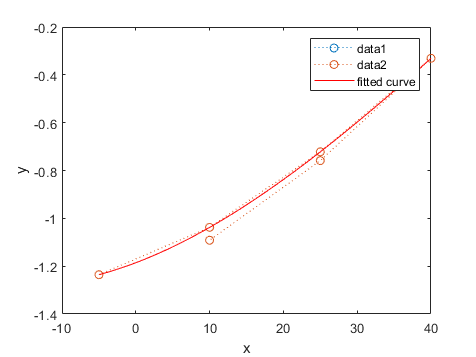


figure(2)
hold ON
plot( [-5, 10, 25, 40, 25, 10], dif_array, "o:")
legend
plot(mdl1)
hold OFF


mdl1.p1

ans =   -2.1461e-06


syms x
latex(y(x) == mdl1.p1 * x^3 + mdl1.p2 * x^2 + mdl1.p3 * x + mdl1.p4)

Error using sym/subsindex
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Error in indexing (line 1075)
            R_tilde = builtin('subsref',L_tilde,Idx);

Related documentation